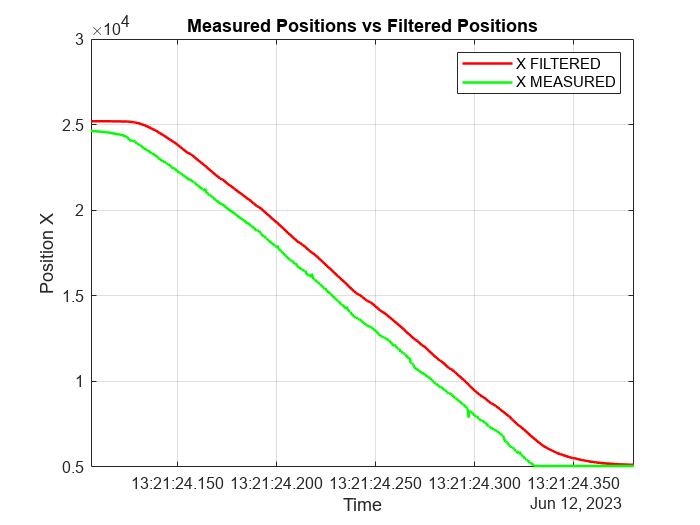

% Define our system parameters
%In thıs code we are tryıng to filter measurments for movinn system in x, y
%and z position usıng kalman fılter
A = eye(3); % assuming that the motion is linear constant over time, as we don t know the real behaviour of the system, from which we found this data 
H = eye(3); % 3x3 measurment matrix and that means that measurment obtained directly reflect the state variables


Q = eye(3) * 1; %assuming some dynamıc noise, ıf the value of our Q is high then uncertıty is high also
R = eye(3) * 1000; % Measurment noise 

% Initialize variables and matrices



P = eye(3); %initial error covariance matrix

% Create logical database

PositionDB = table('Size', [0 4], 'VariableTypes', {'datetime', 'double', 'double', 'double'}, ...
    'VariableNames', {'TimeStamp', 'X', 'Y', 'Z'});




%% Import Dataset
% Important position data

fileID = fopen('3Ddata.txt','r');
formatSpec = '%*s %f %f %f';
sizeA = [3 Inf];
A_pos = fscanf(fileID,formatSpec,sizeA); % Position values in meters

% Import file as single string
fileID = fopen('3Ddata.txt','r');
formatSpec = '%c';
sizeA = [1 Inf];
A_time = fscanf(fileID,formatSpec,sizeA);

% Initialize values

colon = 0;
i = 1;
j = 1;

% Extract time data from string

while i < length(A_time)
    if (A_time(i) == ':')
        colon = colon + 1; %ıncrement colon flag
    end
    if colon == 2 
        colon = 0; %reset the colon flag
        time(j) = str2double(A_time(i+1:i+6)); %store relevant data
        j = j + 1; 
    end
    i = i + 1;
end

% Convert time data to dt values

for i = 1:length(time)-1
    dt(i) = time(i+1)-time(i);
end

dt (dt<0) = dt (dt<0)+60;% eliminate negtiv values

% Assign final measurement values

len = length(A_pos);
x0 = A_pos(1,1);
y0 = A_pos(2,1);
z0 = A_pos(3,1);
x_hat=[x0;y0;z0];
x_pos = A_pos(1,2:len);
y_pos = A_pos(2,2:len);
z_pos = A_pos(3,2:len);

% Generate true positions for x, y, and z

truePositionsX = x_pos;
truePositionsY = y_pos;
truePositionsZ = z_pos;

% Add random noise to simulate measured positions

measuredPositionsX = truePositionsX + rand*0.5;
measuredPositionsY = truePositionsY + rand *0.1;
measuredPositionsZ = truePositionsZ + rand*0.8 ;

% Kalman filter loop

for i = 1:length(measuredPositionsZ)
    % Acquire position measurements
    x_m = measuredPositionsX(i);
    y_m = measuredPositionsY(i);
    z_m = measuredPositionsZ(i);

    % Predict next state and error covariance
    x_hat_minus = A * x_hat;
    P_minus = A * P * A' + Q;

    % Update state estimate and error covariance

    K = P_minus * H' * inv(H * P_minus * H' + R);
    x_hat = x_hat_minus + K * ([x_m; y_m; z_m] - H * x_hat_minus);
    P = (eye(3) - K * H) * P_minus;

    % Store filtered positions in the logical database

    newRow = table(datetime('now'), x_hat(1), x_hat(2), x_hat(3), 'VariableNames', PositionDB.Properties.VariableNames);
    PositionDB = [PositionDB; newRow];
end


% Convert data inputs to double for plotting
time = double(time);
truePositionsX = double(truePositionsX);
truePositionsY = double(truePositionsY);
truePositionsZ = double(truePositionsZ);
measuredPositionsX = double(measuredPositionsX);
measuredPositionsY = double(measuredPositionsY);
measuredPositionsZ = double(measuredPositionsZ);

% Create a meshgrid of coordinates
[timeGrid, trueGridX] = meshgrid(time, truePositionsX);
[timeGrid, trueGridY] = meshgrid(time, truePositionsY);
[timeGrid, trueGridZ] = meshgrid(time, truePositionsZ);

% Plot the true positions, measured positions, and filtered positions in 3D
% Plot the true positions, measured positions, and filtered positions in 3D
% Plot the measured values with filtered values in 2D


figure;
plot(PositionDB.TimeStamp, double(PositionDB.X), 'r', 'LineWidth', 1.5);
hold on;
plot(PositionDB.TimeStamp, measuredPositionsX, 'g', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Position X');
title('Measured Positions vs Filtered Positions');
legend('X FILTERED', 'X MEASURED');
grid on;
hold off;

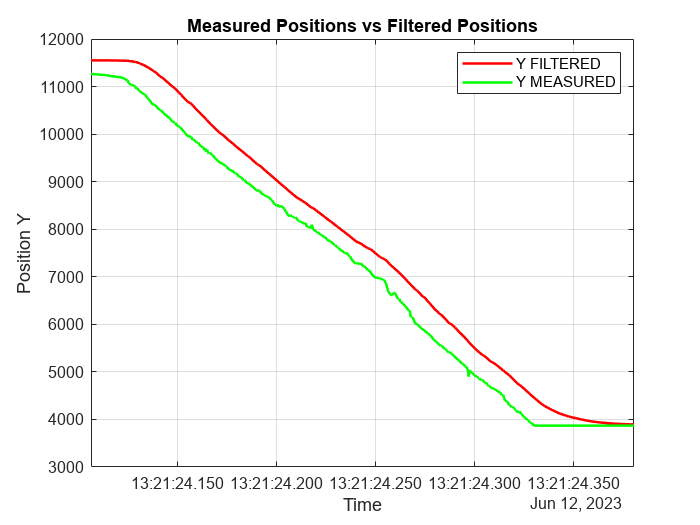




figure;
plot(PositionDB.TimeStamp, double(PositionDB.Y), 'r', 'LineWidth', 1.5);
hold on;
plot(PositionDB.TimeStamp, measuredPositionsY, 'g', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Position Y');
title('Measured Positions vs Filtered Positions');
legend('Y FILTERED', 'Y MEASURED');
grid on;
hold off;

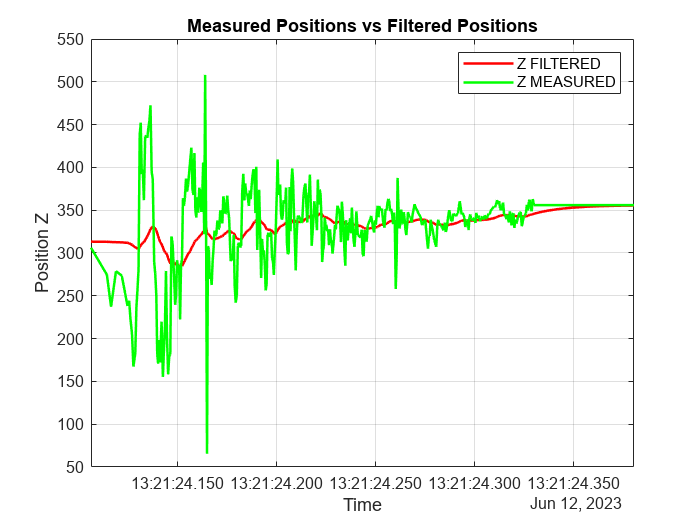


figure;
plot(PositionDB.TimeStamp, double(PositionDB.Z), 'r', 'LineWidth', 1.5);
hold on;
plot(PositionDB.TimeStamp, measuredPositionsZ, 'g', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Position Z');
title('Measured Positions vs Filtered Positions');
legend('Z FILTERED', 'Z MEASURED');
grid on;
hold off

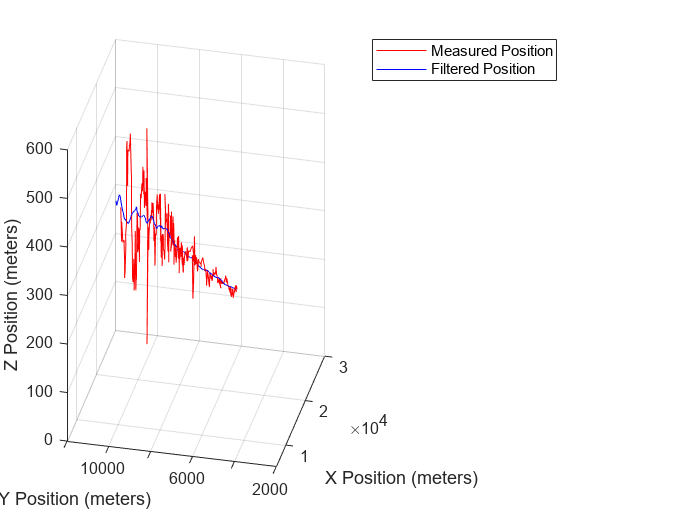



% Reshape X, Y, Z positions into matrices


% Plot the filtered and measured positions in 3D using surf



figure;
plot3(measuredPositionsX,measuredPositionsY,measuredPositionsZ,'r');
hold on;
plot3(PositionDB.X,PositionDB.Y,PositionDB.Z,'b');

legend('Measured Position', 'Filtered Position');
xlabel('X Position (meters)');
ylabel('Y Position (meters)');
zlabel('Z Position (meters)');
grid on;